
[header, seq] = fastaread('ratg13.txt');
genome = seq

genome = 'ATTAAAGGTTTATACCTTTCCAGGTAACAAACCAACGAACTCTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGACTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCATCTATCTTCTGCAGGTTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTCTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGCTTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGTGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCTGATGCTCGAACTGCACCTCATGGCCATGTTATGGTTGAGCTGGTAGCAGAACTTAATGGCATTCAGTATGGTCGTAGTGGTGAGACACTCGGTGTCCTTGTCCCTTATGTGGGCGAAACACCAGTGGTTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCTGATCTAAAGTCGTTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTCACCCGTGATCTCATGCGTGAGCTTAATGGAGGAGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCTCGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAAAGAGGTGTATACTGCTGTCGTGAACATGAGCATGAGATTGCTTGGTACAC


[s,sm] = findClumps(genome(1:1000),4,100,4);
kmers = sm(:,1);
ukmers = unique(kmers);
uukmers=[];
count =[];
for i =1 :length(ukmers)
count = [count ; (sum(kmers == ukmers(i)))];
uukmers =[uukmers ; ukmers(i)];
end
[freq,idx]= sort(count , 'descend');
top10 = ukmers(idx(1:10));
table(top10 , freq(1:10))

ans = 10×2 table
    top10     Var2
    ______    ____

    "ATTA"    172 
    "ACCA"    114 
    "ATGG"    114 
    "TCAA"    113 
    "AAAG"    107 
    "GAAC"     94 
    "CTCC"     83 
    "CACG"     79 
    "AGAT"     53 
    "GAAA"     51 


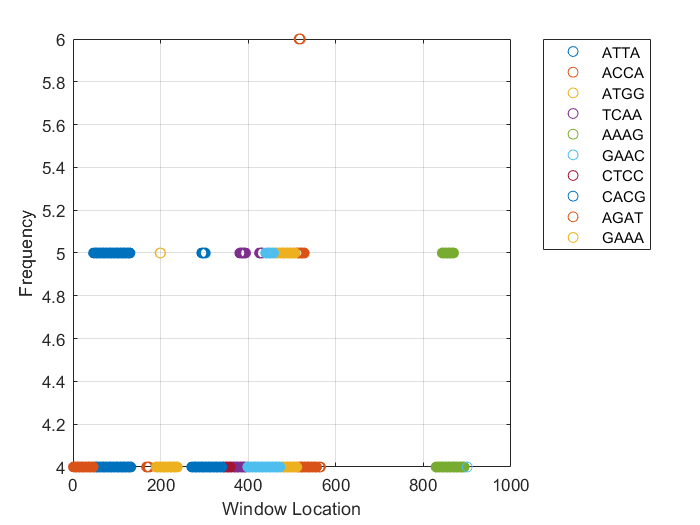


figure
for i=1:10
frequent_occurences= sm(sm(:,1)==top10(i),:);

 plot(double(frequent_occurences(:,2)) ,double(frequent_occurences(:,3)) , 'o' );
hold on

end

legend(top10,'Location','bestoutside')
grid on
xlabel("Window Location")
ylabel("Frequency")
hold off


x = seq

x = 'ATTAAAGGTTTATACCTTTCCAGGTAACAAACCAACGAACTCTCGATCTCTTGTAGATCTGTTCTCTAAACGAACTTTAAAATCTGTGTGACTGTCACTCGGCTGCATGCTTAGTGCACTCACGCAGTATAATTAATAACTAATTACTGTCGTTGACAGGACACGAGTAACTCATCTATCTTCTGCAGGTTGCTTACGGTTTCGTCCGTGTTGCAGCCGATCATCAGCACATCTAGGTTTCGTCCGGGTGTGACCGAAAGGTAAGATGGAGAGCCTTGTCCCTGGTTTCAACGAGAAAACACACGTCCAACTCAGTTTGCCTGTCTTACAGGTTCGCGACGTGCTCGTACGTGGCTTTGGAGACTCCGTGGAGGAGGCTTTATCAGAGGCACGTCAACATCTTAAAGATGGCACTTGTGGCTTAGTAGAAGTTGAAAAAGGTGTTTTGCCTCAACTTGAACAGCCCTATGTGTTCATCAAACGTTCTGATGCTCGAACTGCACCTCATGGCCATGTTATGGTTGAGCTGGTAGCAGAACTTAATGGCATTCAGTATGGTCGTAGTGGTGAGACACTCGGTGTCCTTGTCCCTTATGTGGGCGAAACACCAGTGGTTTACCGCAAGGTTCTTCTTCGTAAGAACGGTAATAAAGGAGCTGGTGGCCATAGTTACGGCGCTGATCTAAAGTCGTTTGACTTAGGCGACGAGCTTGGCACTGATCCTTATGAAGATTTTCAAGAAAACTGGAACACTAAACATAGCAGTGGTGTCACCCGTGATCTCATGCGTGAGCTTAATGGAGGAGCATACACTCGCTATGTCGATAACAACTTCTGTGGCCCTGATGGCTACCCTCTTGAGTGCATTAAAGACCTTCTAGCTCGTGCTGGTAAAGCTTCATGCACTTTGTCCGAACAACTGGACTTTATTGACACTAAAAGAGGTGTATACTGCTGTCGTGAACATGAGCATGAGATTGCTTGGTACACGGAAC

temp=strrep(strrep(strrep(strrep( x ,'A','*'),'C','.'),'T','A'),'G','C');
y = strrep(strrep(temp,'*','T'),'.','G')

y = 'TAATTTCCAAATATGGAAAGGTCCATTGTTTGGTTGCTTGAGAGCTAGAGAACATCTAGACAAGAGATTTGCTTGAAATTTTAGACACACTGACAGTGAGCCGACGTACGAATCACGTGAGTGCGTCATATTAATTATTGATTAATGACAGCAACTGTCCTGTGCTCATTGAGTAGATAGAAGACGTCCAACGAATGCCAAAGCAGGCACAACGTCGGCTAGTAGTCGTGTAGATCCAAAGCAGGCCCACACTGGCTTTCCATTCTACCTCTCGGAACAGGGACCAAAGTTGCTCTTTTGTGTGCAGGTTGAGTCAAACGGACAGAATGTCCAAGCGCTGCACGAGCATGCACCGAAACCTCTGAGGCACCTCCTCCGAAATAGTCTCCGTGCAGTTGTAGAATTTCTACCGTGAACACCGAATCATCTTCAACTTTTTCCACAAAACGGAGTTGAACTTGTCGGGATACACAAGTAGTTTGCAAGACTACGAGCTTGACGTGGAGTACCGGTACAATACCAACTCGACCATCGTCTTGAATTACCGTAAGTCATACCAGCATCACCACTCTGTGAGCCACAGGAACAGGGAATACACCCGCTTTGTGGTCACCAAATGGCGTTCCAAGAAGAAGCATTCTTGCCATTATTTCCTCGACCACCGGTATCAATGCCGCGACTAGATTTCAGCAAACTGAATCCGCTGCTCGAACCGTGACTAGGAATACTTCTAAAAGTTCTTTTGACCTTGTGATTTGTATCGTCACCACAGTGGGCACTAGAGTACGCACTCGAATTACCTCCTCGTATGTGAGCGATACAGCTATTGTTGAAGACACCGGGACTACCGATGGGAGAACTCACGTAATTTCTGGAAGATCGAGCACGACCATTTCGAAGTACGTGAAACAGGCTTGTTGACCTGAAATAACTGTGATTTTCTCCACATATGACGACAGCACTTGTACTCGTACTCTAACGAACCATGTGCCTTG


answer = getStats(seq,1)

answer =   Map with properties:

        Count: 4
      KeyType: char
    ValueType: any


base = 'CGAT';
displs =[];
for i = 1:length(base)
stats = answer(base(i));
total = stats(1);
forwardCount = stats(2);
reverseCount = stats(3);
displs = [displs ; convertCharsToStrings(base(i)) num2str(total) num2str(forwardCount) num2str(reverseCount) num2str(forwardCount-reverseCount)];

end
table(displs(:,1),displs(:,2),displs(:,3),displs(:,4),displs(:,5));

ans.Var2 = double(ans.Var2);
ans.Var3 = double(ans.Var3);
ans.Var4 = double(ans.Var4);
ans.Var5 = double(ans.Var5);
% GC SKEW
[x,y] = GCSkew(seq);
[val,idx] = max(y)

val = 330

idx = 60

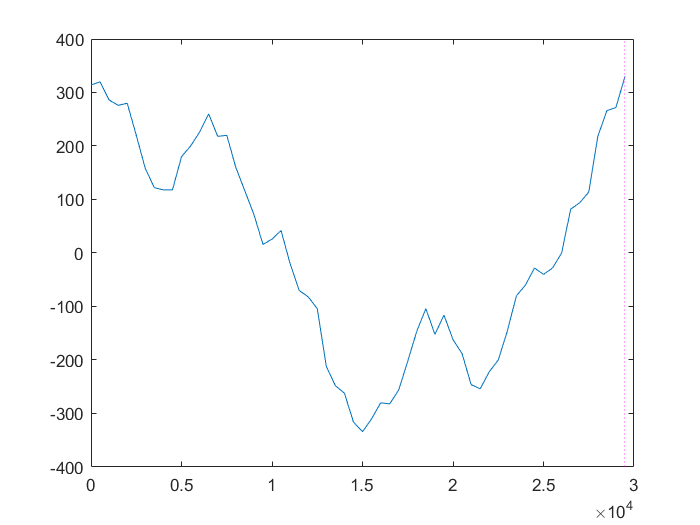

plot(x,y)
xline (x(idx),':m')

function [pp] = kmerPositions(k,seq)

kmerPosition = containers.Map;
for i=1:length(seq)-k+1
kmer = seq(i:i+k-1);

 if(kmerPosition.isKey(kmer))
kmerPosition(kmer) =sort( [kmerPosition(kmer) i] );
else
kmerPosition(kmer)=i;
end
end

keysss = kmerPosition.keys;
positions = kmerPosition.values;

pairPosition = containers.Map;
for i=1:kmerPosition.Count
kmer = keysss{i};
poslist = positions{i};

 temp=strrep(strrep(strrep(strrep( kmer(end:-1:1) ,'A','*'),'C','.'),'T','A'),'G','C');
krev = strrep(strrep(temp,'*','T'),'.','G');

 if( convertCharsToStrings(kmer) < convertCharsToStrings(krev))
if(kmerPosition.isKey(krev))
pairPosition(kmer) = sort([poslist, kmerPosition(krev)] );
else
pairPosition(krev) = sort(poslist);
end
elseif(convertCharsToStrings(krev) < convertCharsToStrings(kmer))
if(kmerPosition.isKey(krev))
pairPosition(krev) = sort([kmerPosition(krev),poslist]);
else
pairPosition(krev) = sort(poslist);
end
else
pairPosition(kmer)=poslist;
end
pp = pairPosition;

end

end
function [clumpps,boxclumps] = findClumps(string, k , L , t)

clumps=[];
bclumps =[];

 for i=1:length(string)-L
start = i;
END = i+L-1;
box = string(start:END);
kmerpositions = kmerPositions(k,box);
kmers = kmerpositions.keys;
positions = kmerpositions.values;
for j=1:kmerpositions.Count
kmer = kmers{j};
poslist = positions{j};
for k_ = 1:length(poslist)
count = sum((poslist>=poslist(k_)) .* (poslist < poslist(k_)+L) );
if count>=t
Clump.kmer = kmer;
Clump.position = i;
Clump.count = count;
clumps = [clumps Clump];
bclumps = [bclumps ;convertCharsToStrings(kmer) i count];
end
end
end
end
clumpps = clumps;
boxclumps = bclumps;
end
function[stats] = getStats(sequence, start)
halflen = floor(length(sequence)/2);
terC = start + halflen;
if (terC > length(sequence))
terC = terC - length(sequence) + 1;
end
stats = containers.Map;
base = 'ACGT';
for i = 1:length(base)
total = count(sequence,base(i));
if (terC > start)
forwardCount = count(sequence(start:terC), base(i));
reverseCount = total - forwardCount;
else
reverseCount = count(sequence(start:terC), base(i));
forwardCount = total - reverseCount;
end
stats(base(i)) = [total, forwardCount, reverseCount];
end
end
function[rtn] = getGCdiff(sequence, start)
halflen = floor(length(sequence)/2);
terC = start + halflen;
if (terC > length(sequence))
terC = terC - length(sequence) + 1;
end
if (terC > start)
G = 2*count(sequence(start:terC), 'G') - count(sequence , 'G');
C = 2*count(sequence(start:terC), 'C') - count(sequence , 'C');
else
G = count(sequence , 'G') - (2*count(sequence(terC:start), 'G'));
C = count(sequence , 'C') - (2*count(sequence(terC:start), 'C'));
end
rtn = G - C;
end

function[x,y] = GCSkew(genome)
x = []; y = [];
temp = 1:500:length(genome);
for i = 1:length(temp)
x = [x temp(i)];
y = [y getGCdiff(genome, temp(i))];
end
end